# PRÁCTICA SW1

#### Maria José Medina y Teresa González

## 1. Introducción

En esta práctica se utiliza el método de la bisección para resolver una ecuación del tipo $f(x)= 0$, el cual se basa en el teorema de Bolzano. Este teorema garantiza la existencia de, al menos una raíz en un intervalo [a,b] si la función en ambos extremos del intervalo tiene distinto signo.

## 2. Explicación del método de la bisección

El método de la bisección consiste en, para un intervalo en el que sus extremos tienen distintos símbolos, encontrar la raíz dentro de dicho intervalo.

Se busca la raíz calculando el punto medio del intervalo, y evaluando si tiene el mismo el signo que los extremos. Si tiene el signo igual a alguno de los extremos, se actualiza dicho extremo al valor del punto medio, y se recalcula el punto medio.

Así, se va estrechando el intervalo hasta cierto número de iteraciones, o hasta que se la diferencia entre extremos sea menor que una cierta tolerancia. En ese caso, se considera raíz el punto medio actual.

## 3. Aplicación del método de la bisección

A continuación, se aplica el algoritmo de la bisección para resolver las siguientes ecuaciones:

$x = e^x - 3$ (1)

$J_l(x)=x^2-x$ (2), siendo J la función de bessel de primer tipo y orden l.

### 3.1 Ecuación 1

Inicialmente, se representa la función $x = e^x - 3$ (1) en el rango [-5, 5], para observar en qué valores se encuentran las raíces aproximadamente.

Visualmente, hay una raíz en x= -3  y otra en x=1.5, aproximadamente.

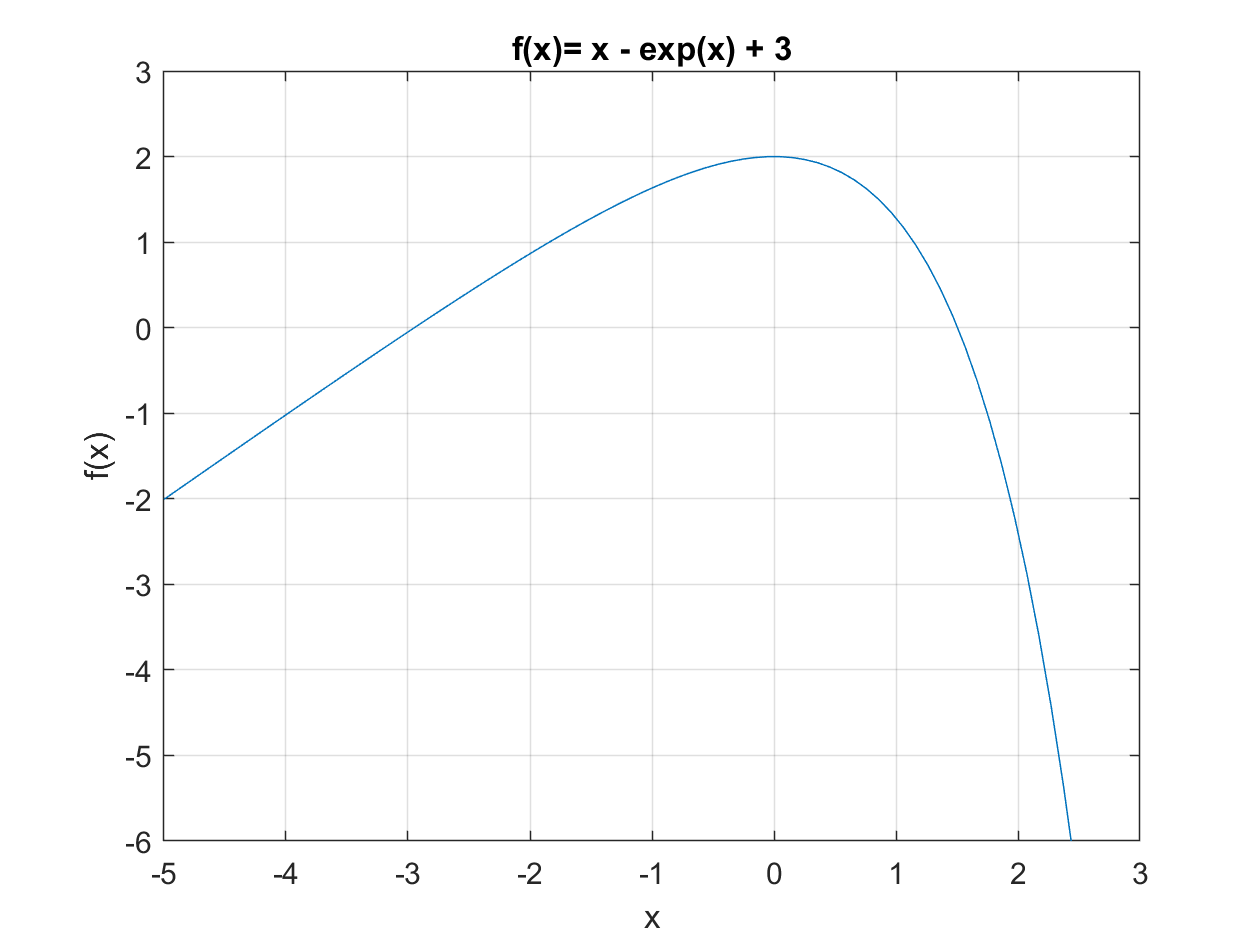

% Definición función
f1= @(x) (x - exp(x) + 3);

%Vector x
x=linspace(-5,5);

% Representación
figure
plot(x, f1(x))
ylim([-6,3])
grid
title('f(x)= x - exp(x) + 3');
xlabel('x')
ylabel('f(x)')

A continuación, se calculan analíticamente las salidas por el método de la bisección. Se utiliza una tolerancia del orden de $10^{-5}$ y un millón de iteraciones. El intervalo elegido es de 0 a 3 para la raíz positiva y de -3 a 0 para la raíz negativa.

%Cálculo de las 2 raíces
x0=myBisection(f1,0,3,1e06,1e-05)

x0 = 1.5052

x1=myBisection(f1,-3,0,1e06,1e-05)

x1 = -2.9475

Se comprueba que el método funciona correctamente, y encuentra unas raíces de x0= 1.5052 y x1= -2.9475, que coinciden con las observadas anteriormente.

### 3.2 Ecuación 2

Inicialmente, se representa la función $J_l(x)=x^2-x$ (2) en el rango [0.1, 5], para observar en qué valores se encuentran las raíces aproximadamente. Además, se utilizan los valores de l= {0,1} para el orden de la función Bessel.

Inicialmente, se representan las 2 funciones en el rango [-5, 5] para ver cómo varía el comportamiento en función del orden.

 A continuación, se representan las funciones en el rango requerido para ver las raíces. Visualmente, hay una única raíz en x= 1.4  para l=0 y otra en x=1.5 para l=1, aproximadamente.

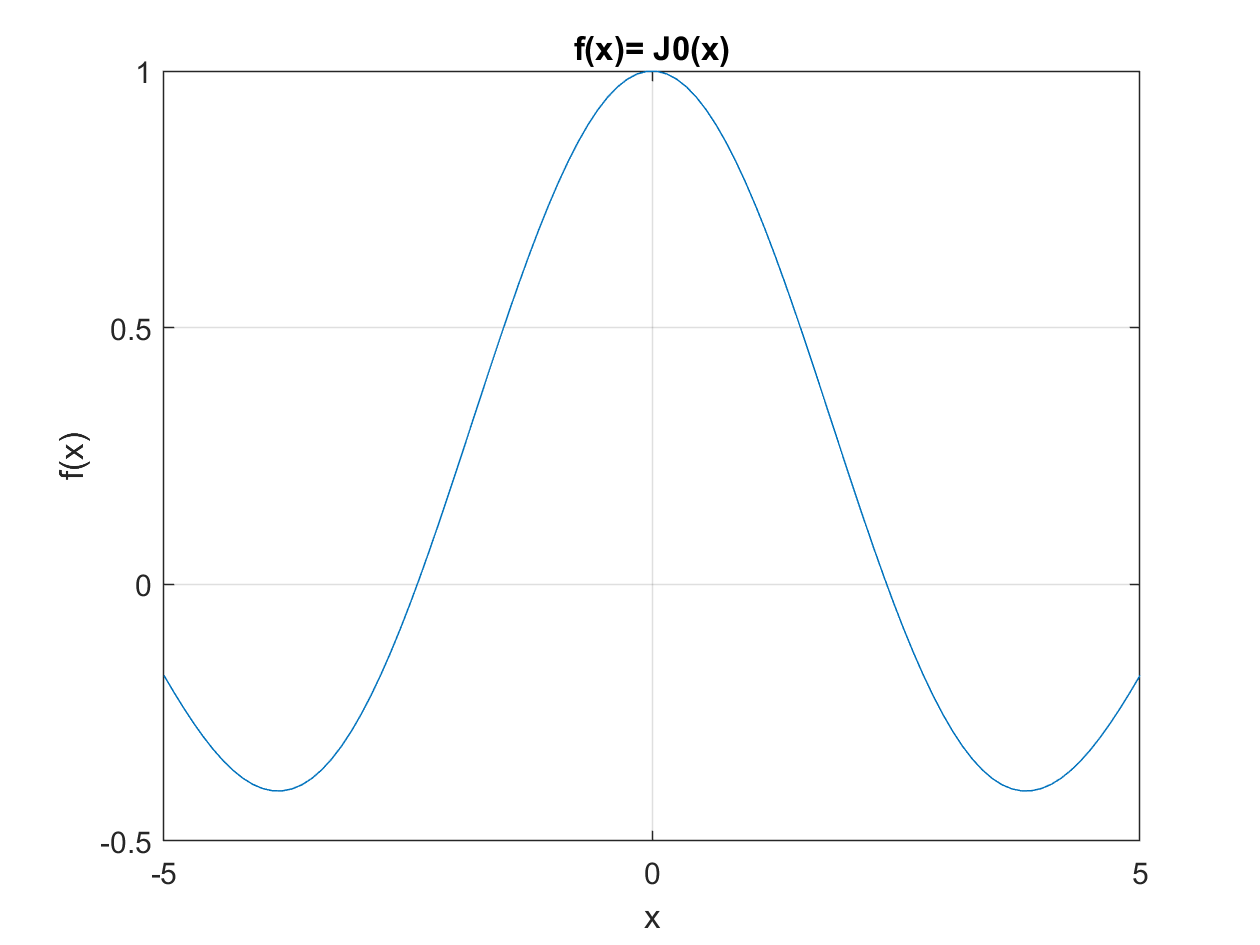

% Definición funciones Bessel 
J0= @(x) (besselj(0,x));
J1= @(x) (besselj(1,x));

f2_0= @(x) (J0(x) -x.^2 +x);
f2_1= @(x) (J1(x) -x.^2 +x);


%Representación J0 en rango [-5,5]
figure
plot(x, J0(x))
grid
title('f(x)= J0(x)');
xlabel('x')
ylabel('f(x)')

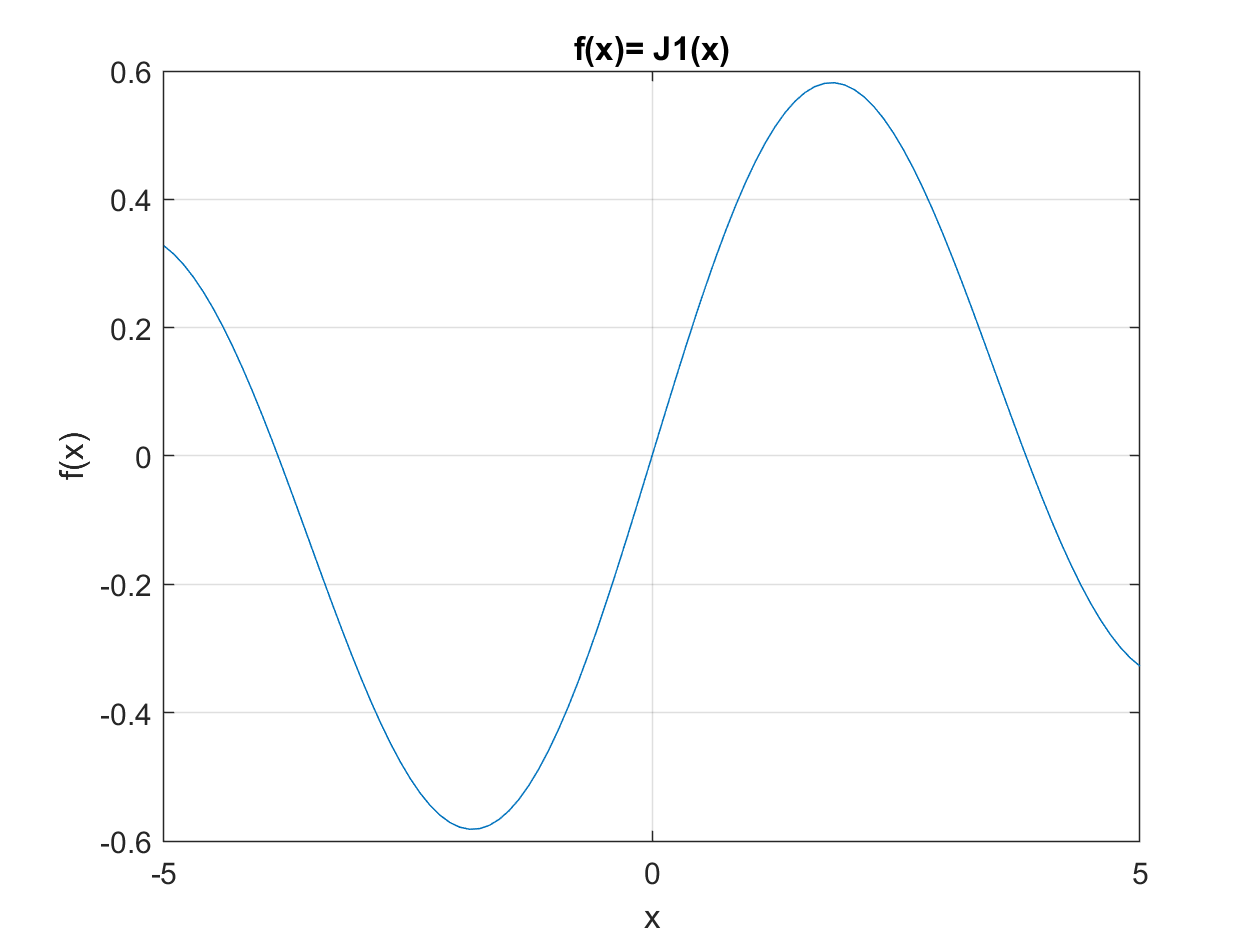


%Representación J1 en rango [-5,5]
figure
plot(x, J1(x))
grid
title('f(x)= J1(x)');
xlabel('x')
ylabel('f(x)')

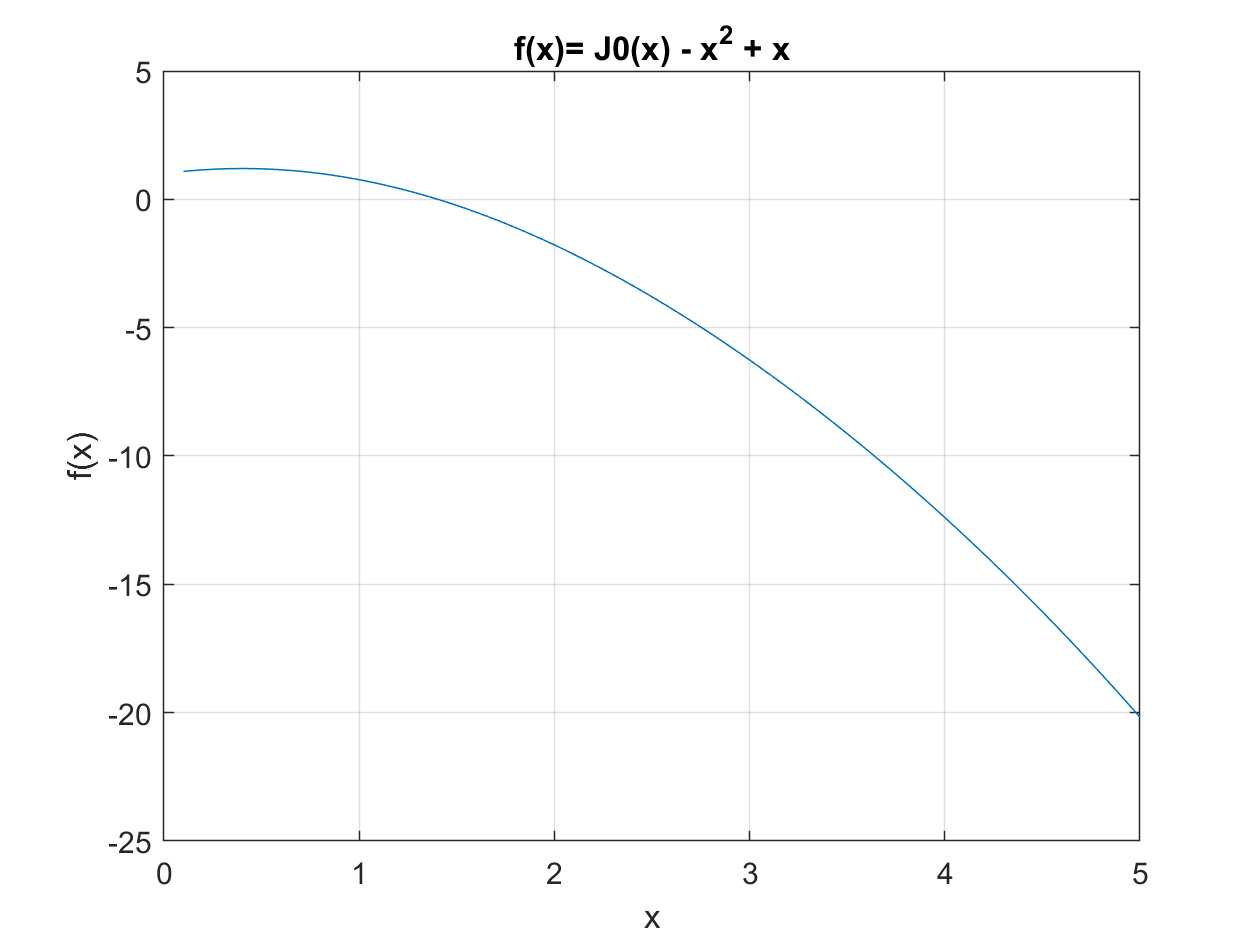


% PLOTS
x=linspace(0.1,5);
figure
plot(x, f2_0(x))
grid

title('f(x)= J0(x) - x^2 + x');
xlabel('x')
ylabel('f(x)')

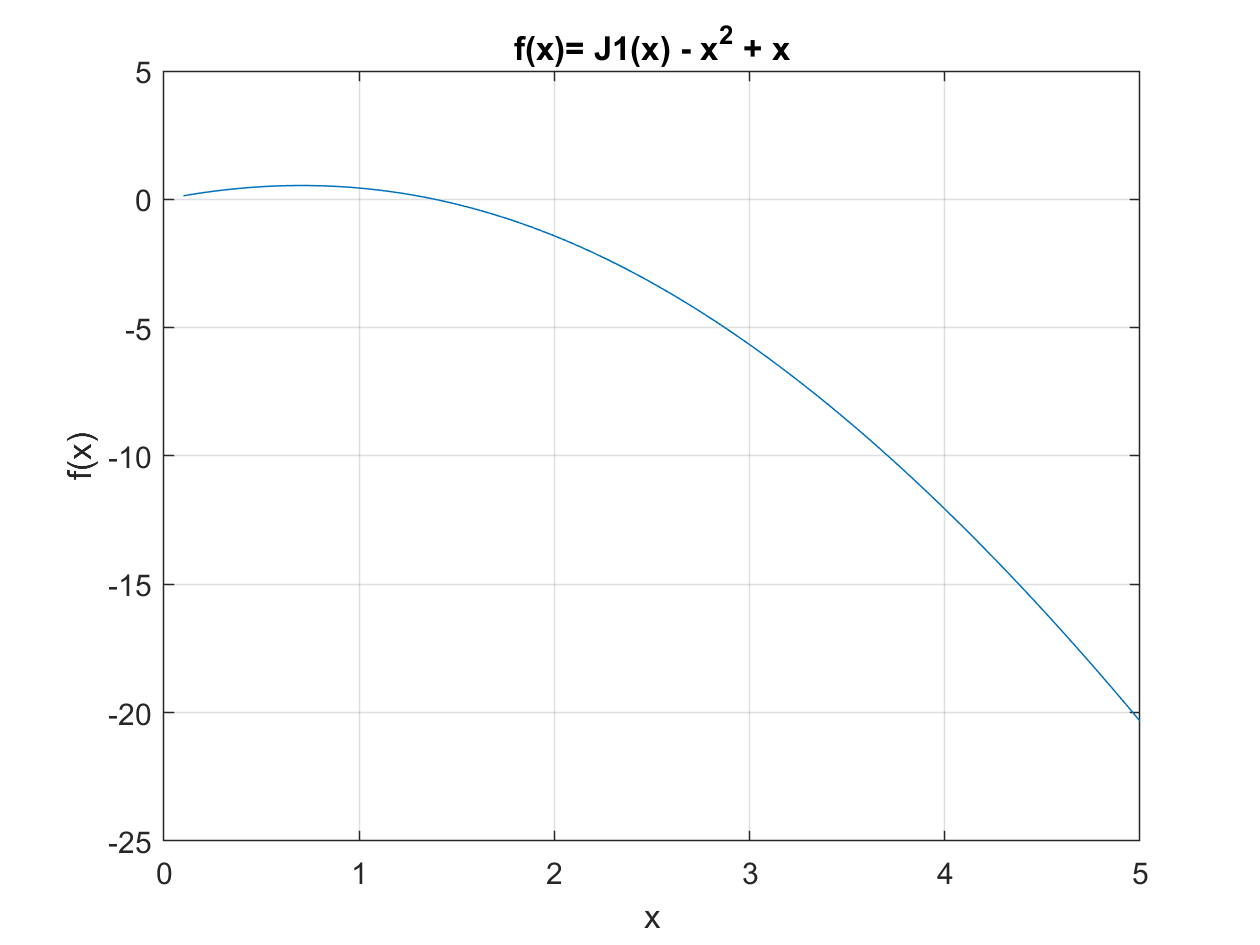


figure
plot(x, f2_1(x))
grid
title('f(x)= J1(x) - x^2 + x');
xlabel('x')
ylabel('f(x)')

A continuación, se calculan analíticamente las salidas por el método de la bisección. Se utiliza una tolerancia del orden de $10^{-5}$ y un millón de iteraciones. El intervalo elegido es de 0.1 a 5 para ambas funciones.

%RAICES
%J0
x0=myBisection(f2_0,0.1,5,1e06,1e-05)

x0 = 1.4029

%J1
x1=myBisection(f2_1, 0.1,5,1e06,1e-05)

x1 = 1.3888

De nuevo, se verifica que el método funciona correctamente, y encuentra unas raíces de x0= 1.4029 y x1= 1.3888, que coinciden con las observadas anteriormente.